# ASTE 575 Problem 19

## Part a

p1 = 10;
r1 = 0.3;
p2 = 50;
r2 = 0.6;

n = (log10(r2) - log10(r1))/(log10(p2) - log10(p1))

n = 0.4307

b = log10(r1) - n*log10(p1);
a = 10^b

a = 0.1113

r = @(p) a*p.^n; %cm/s


$$r(p) = 0.1113p^{0.4307}$$


## Part b

p0 = 90; %atm
R0 = 32; %cm
R1 = 10; %cm
h = p0^(1 - n)/(2*pi*R0); %cm
p = @(R) (2*pi*R*h)^(1/(1 - n)); %atm
p1 = p(R1) %atm

p1 = 11.6671

## Part c

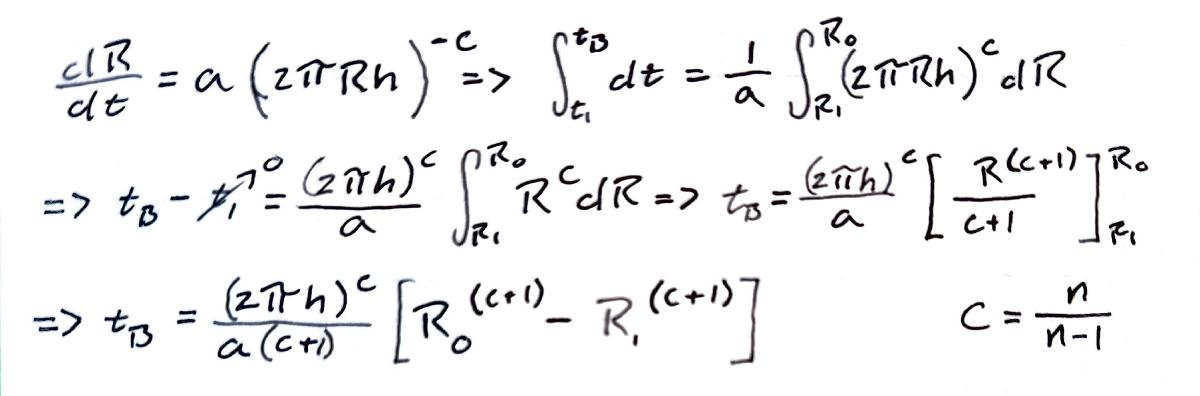

c = n/(n - 1);
tb = (2*pi*h)^c/(a*(c + 1))*(R0^(c + 1) - R1^(c + 1)) %s

tb = 41.9408

## Part d

t2 = 20; %s
F1 = 20; %kN
R2 = (a*(c + 1)*(2*pi*h)^(-c)*t2 + R1^(c + 1))^(1/(c + 1)); %cm
p2 = p(R2); %atm
F2 = F1*p2/p1 %kN

F2 = 56.9538